clear all
close all
DBLoss = -0.3; % dB/km
L = 10; %km
D = 20; %ps/nm/km
wavelwngth = 1.55; % um
delta_lambda = 0.2; %nm
signal_power = 1e9; % 1mw = 1e9pw
B_1 = 1; % Gb/s
B_10 = 10; % Gb/s

fc = 5; %GHz 

Interval_1 = 1/B_1; %ns
Interval_2 = 1/B_10; %ns

tau_0 = 0.01; %ns

fs = 1000; %1000Hz*(1s/1ns)

t = -0.1:(1/fs):0.1; %ns

Original Signal

P = zeros(1,length(t));
P = P + signal_power * exp(-(t+0.05).^2/2/tau_0^2);
P = P + signal_power * exp(-(t-0.05).^2/2/tau_0^2);

Transmission Loss

RLoss = 10^(L*DBLoss/10); %Ratio Loss

Dispersion

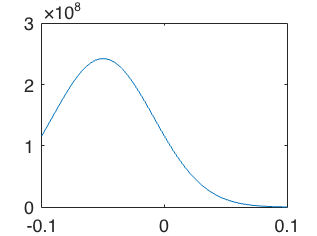

delta_tau = D*delta_lambda*L/1000; %ns
tau = (tau_0.^2 + delta_tau^2).^0.5; % pulse width considering dispersion
P = zeros(1,length(t));
P = P + signal_power/(tau/tau_0)*exp(-(t+0.05).^2/2/tau^2);
plot(t,P)

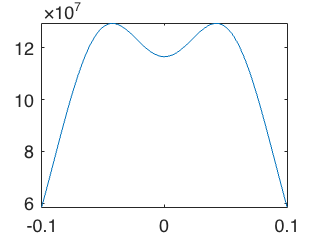

P = P + signal_power/(tau/tau_0)*exp(-(t-0.05).^2/2/tau^2);
P = P * RLoss;
plot(t,P)

Shot Noise

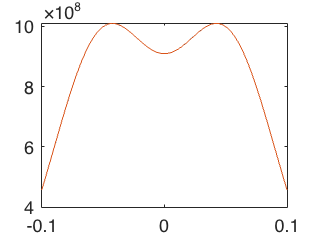

tstep = 1/fs;  % ns
Uphoton = physconst('LightSpeed')*6.62607015*10^(-34)/wavelwngth * 10^12; %pj
P= tstep * 1e-9 / Uphoton .* P;
plot(t,P)
hold on
P = poissrnd(P);
plot(t,P)
hold off

Reciever Noise

NEP = 2; %Units are pW/sqrt(Hz)
Pnoise = NEP * (fs/2*1e9)^0.5;
Nnoise_rms = Pnoise * tstep * 1e-9 / Uphoton;
Nnoise = normrnd(0,Nnoise_rms,[1,length(t)]);
P = P + Nnoise;
plot(t,P)
hold on

Filter

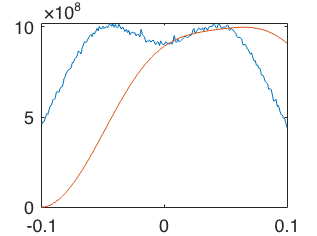

[b,a] = butter(2,fc/(fs/2));

dataIn = P;
P_filt = filter(b,a,P);
plot(t,P_filt)